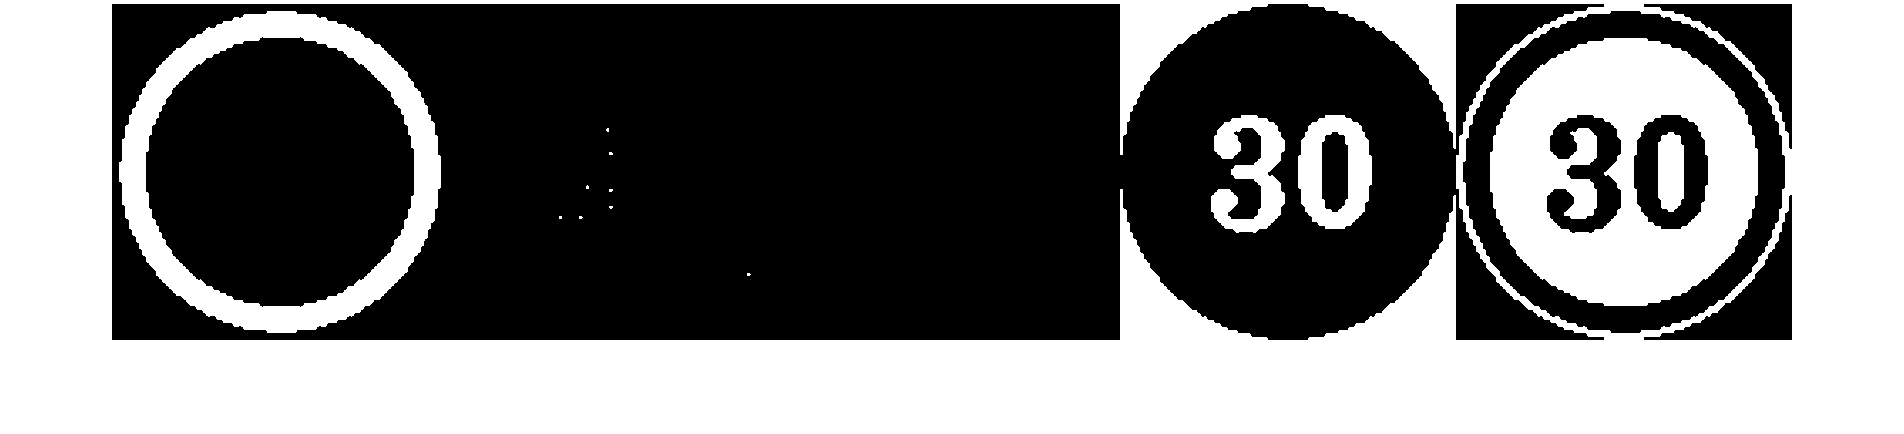

displaySign(1)

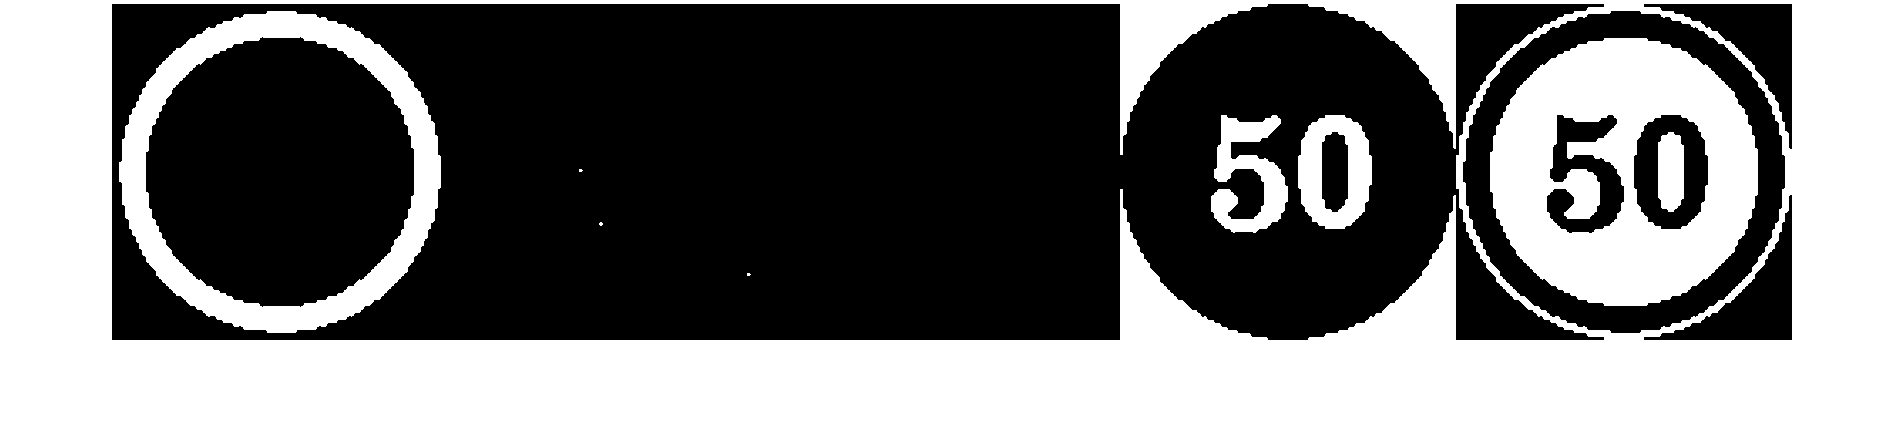

displaySign(2)

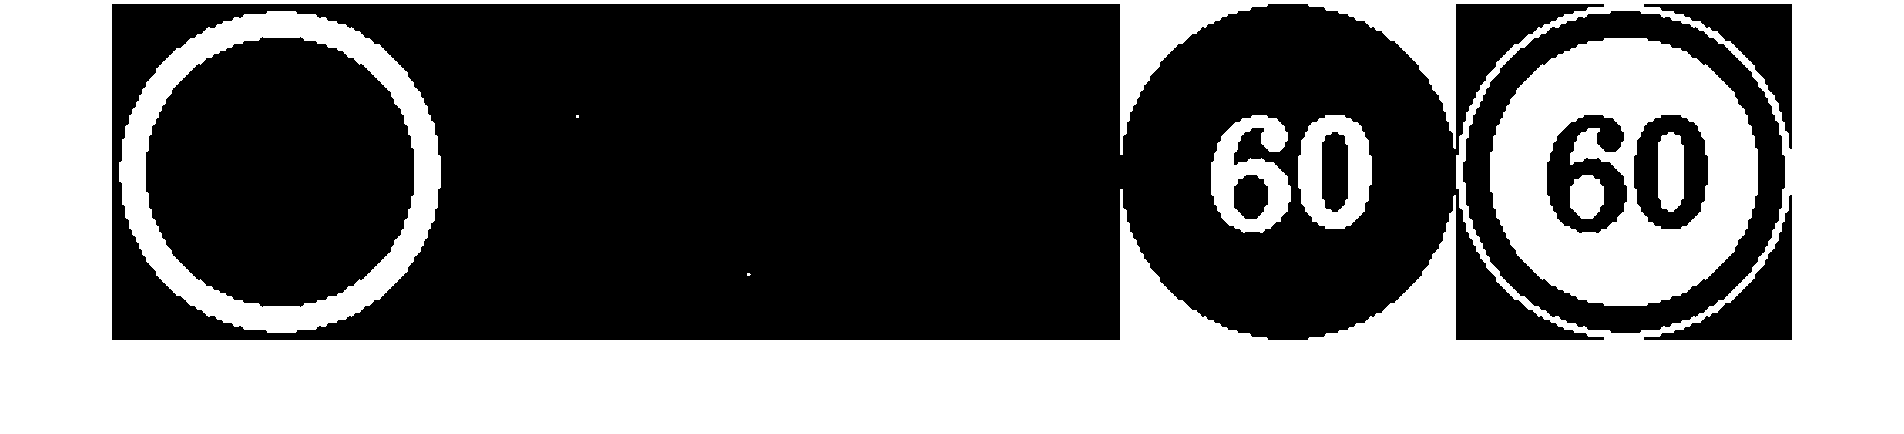

displaySign(3)

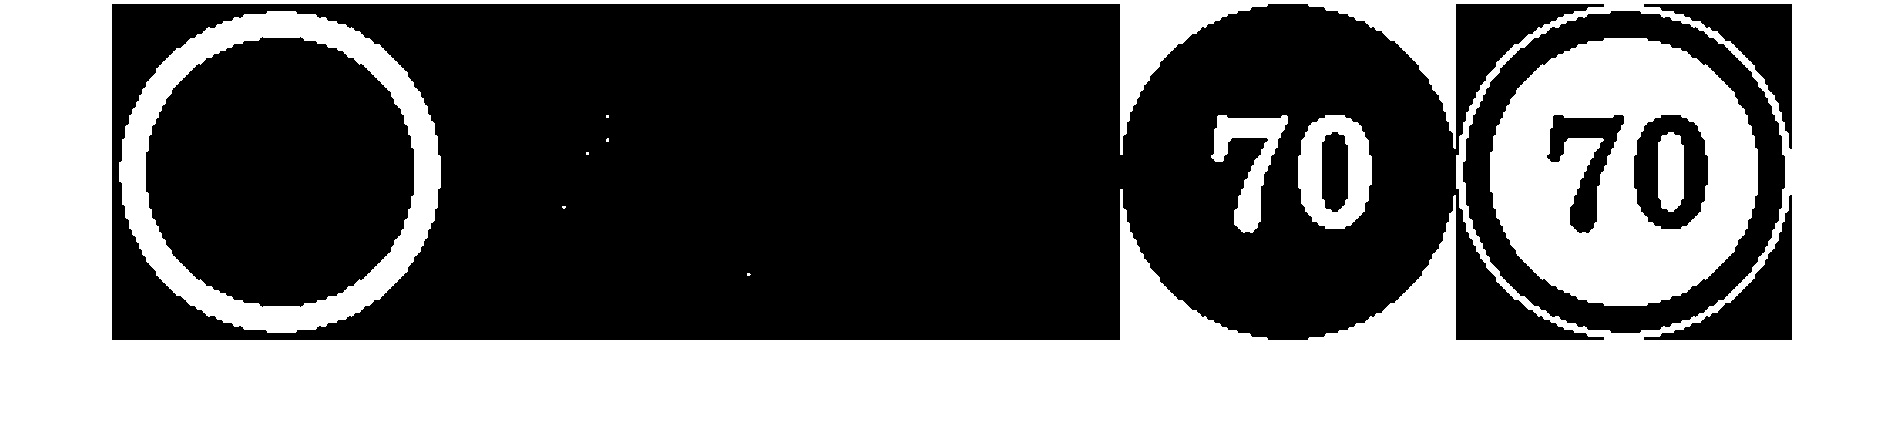

displaySign(4)

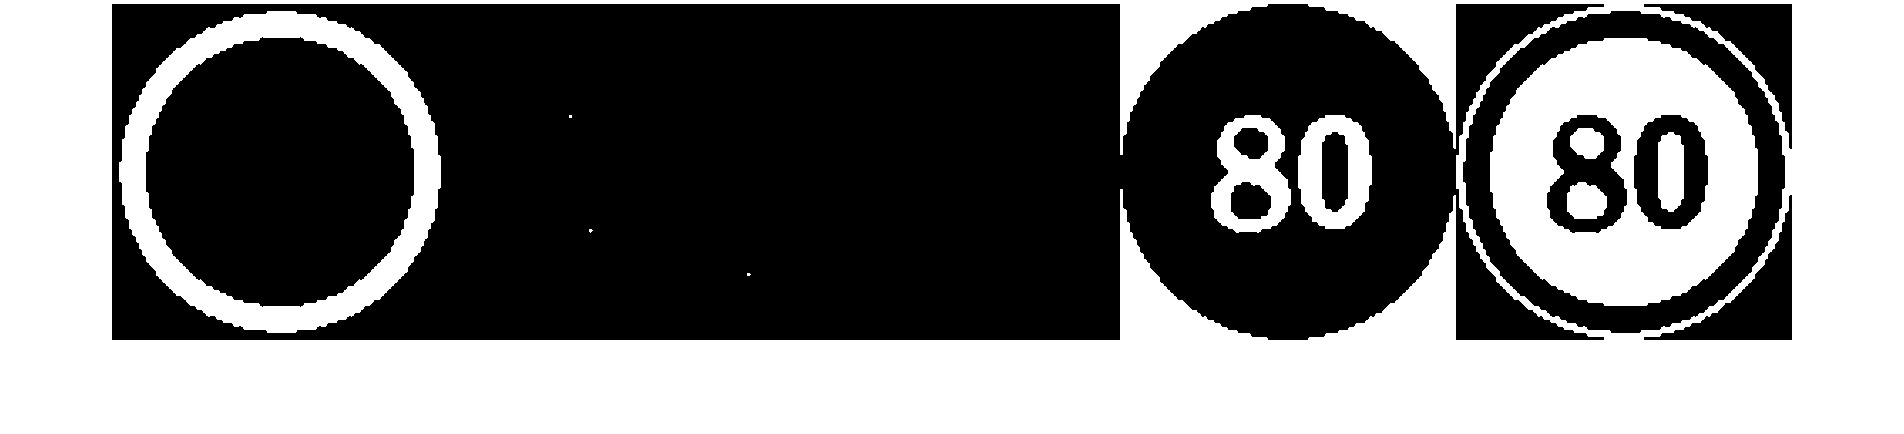

displaySign(5)

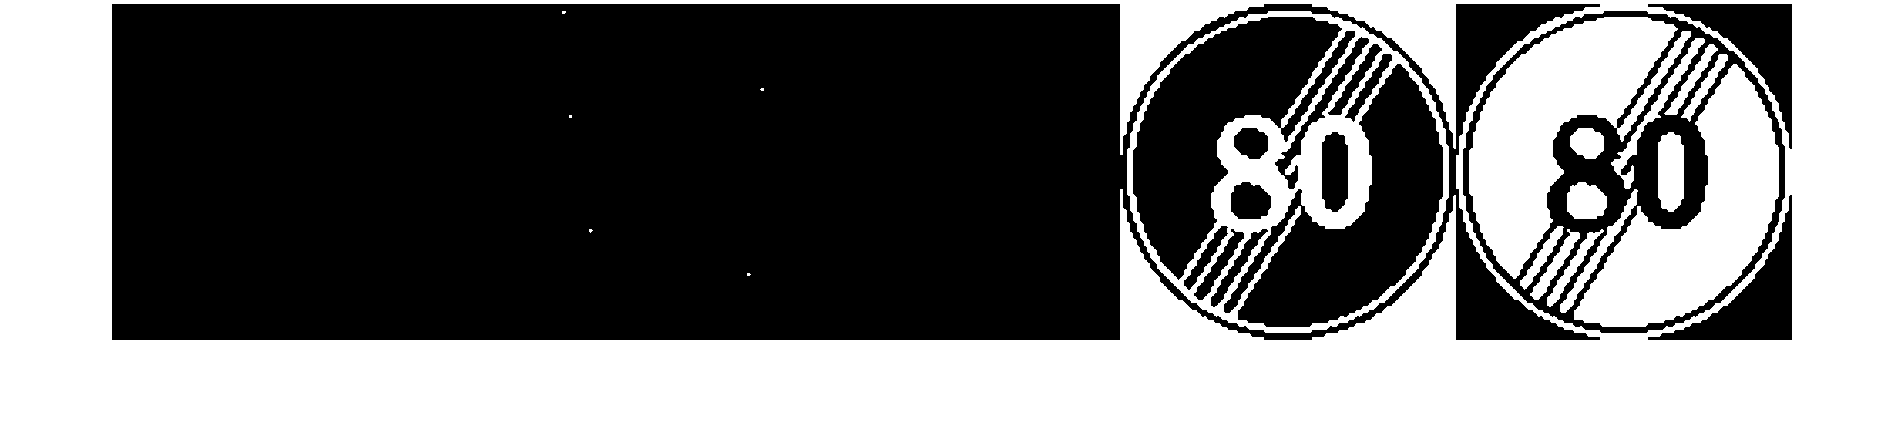

displaySign(6)

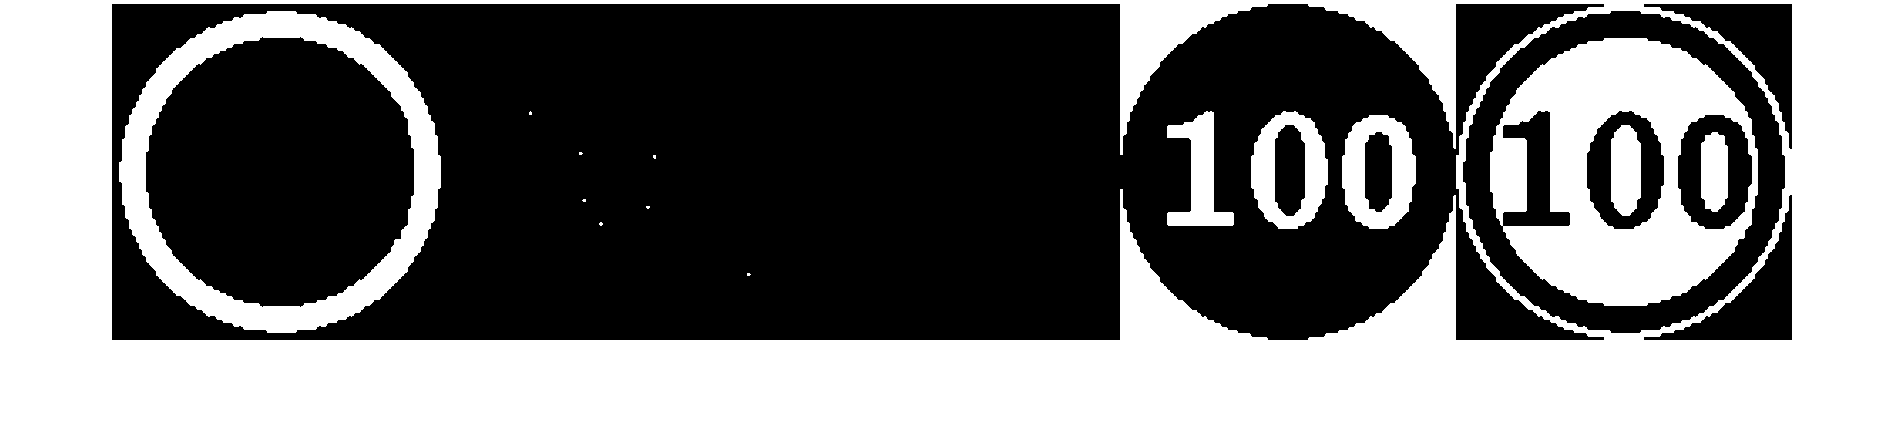

displaySign(7)

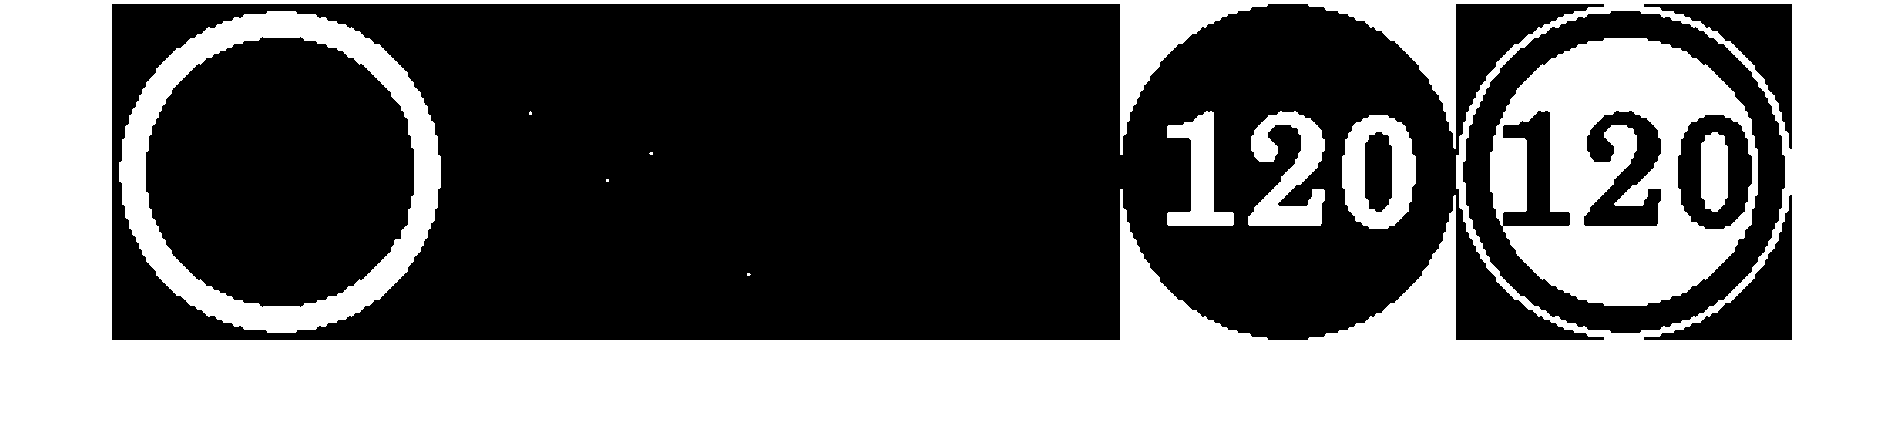

displaySign(8)

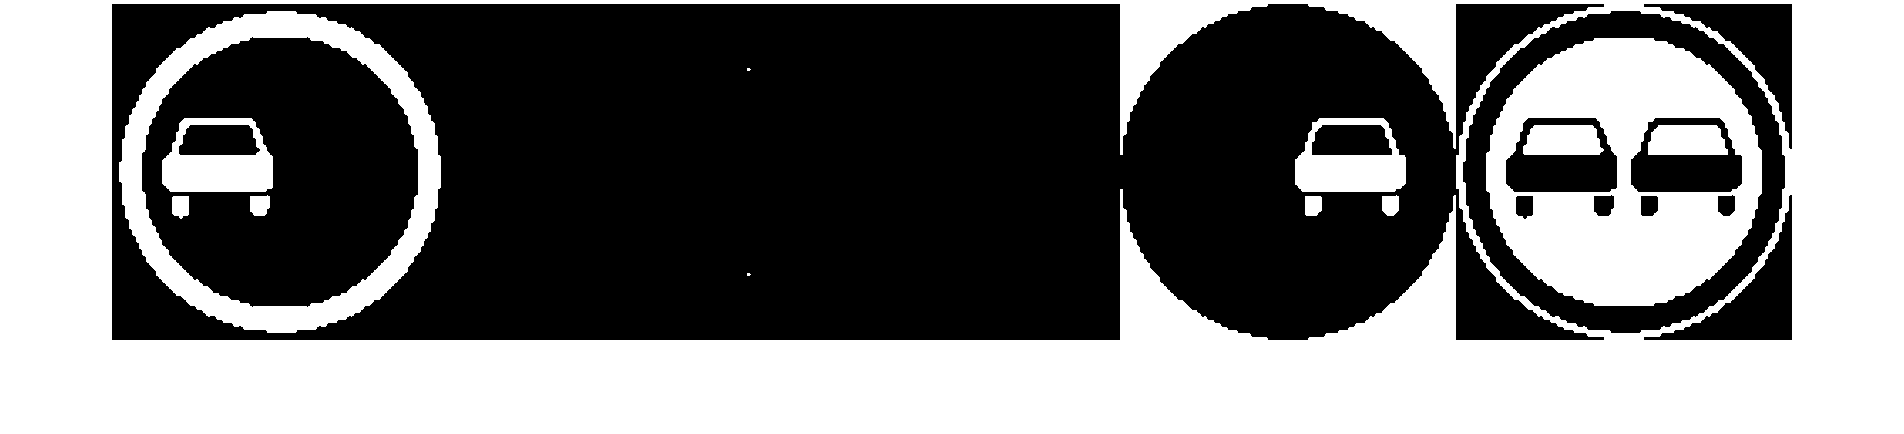

displaySign(9)

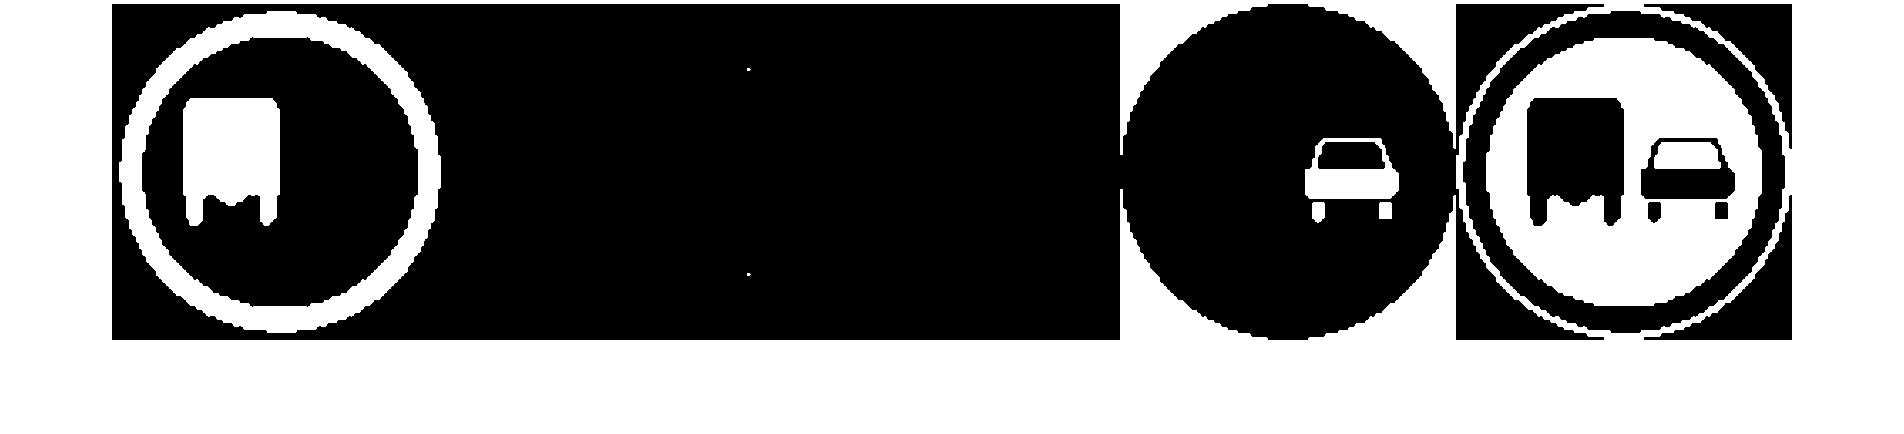

displaySign(10)

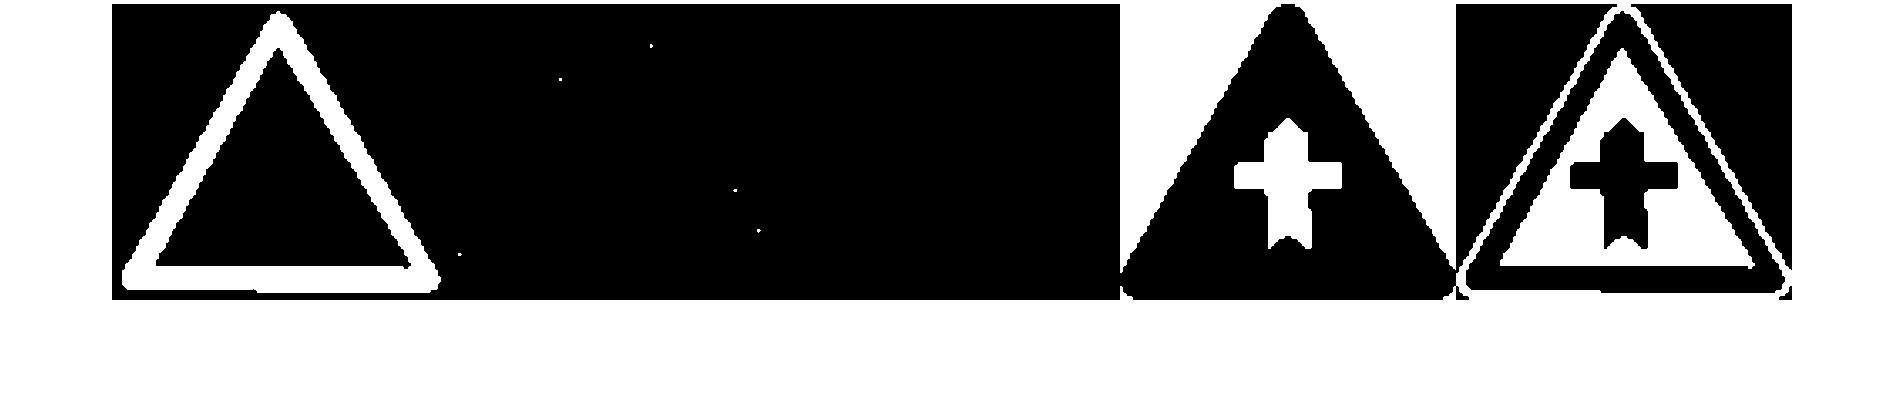

displaySign(11)

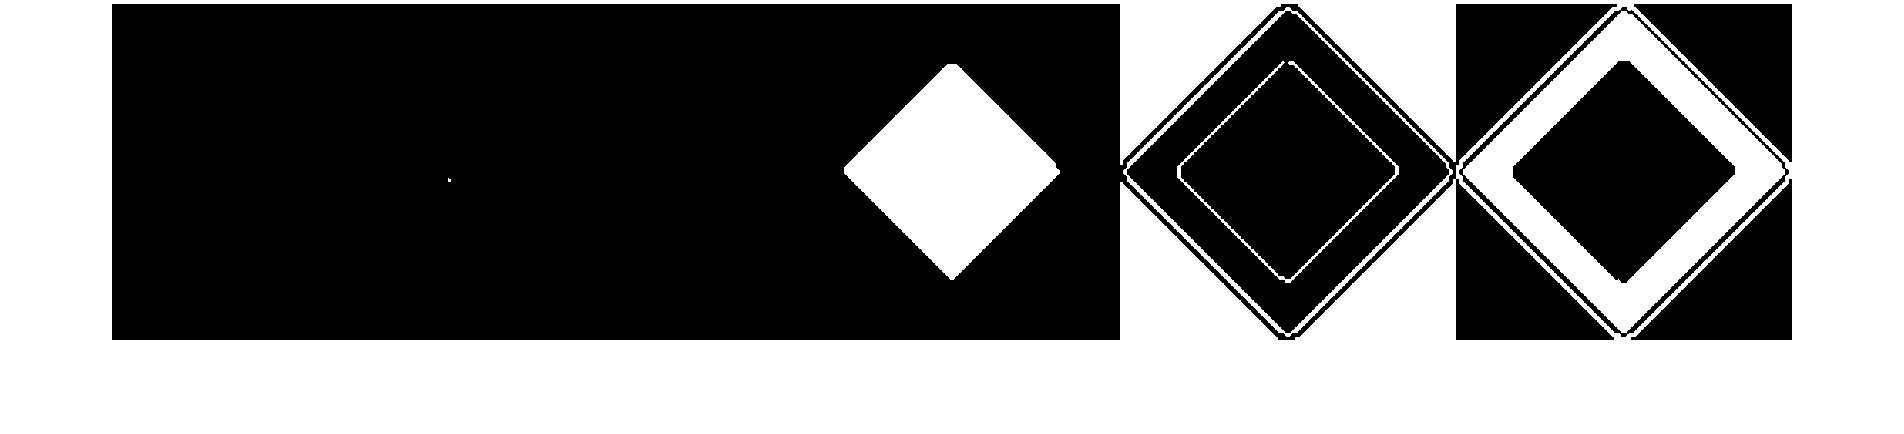

displaySign(12)

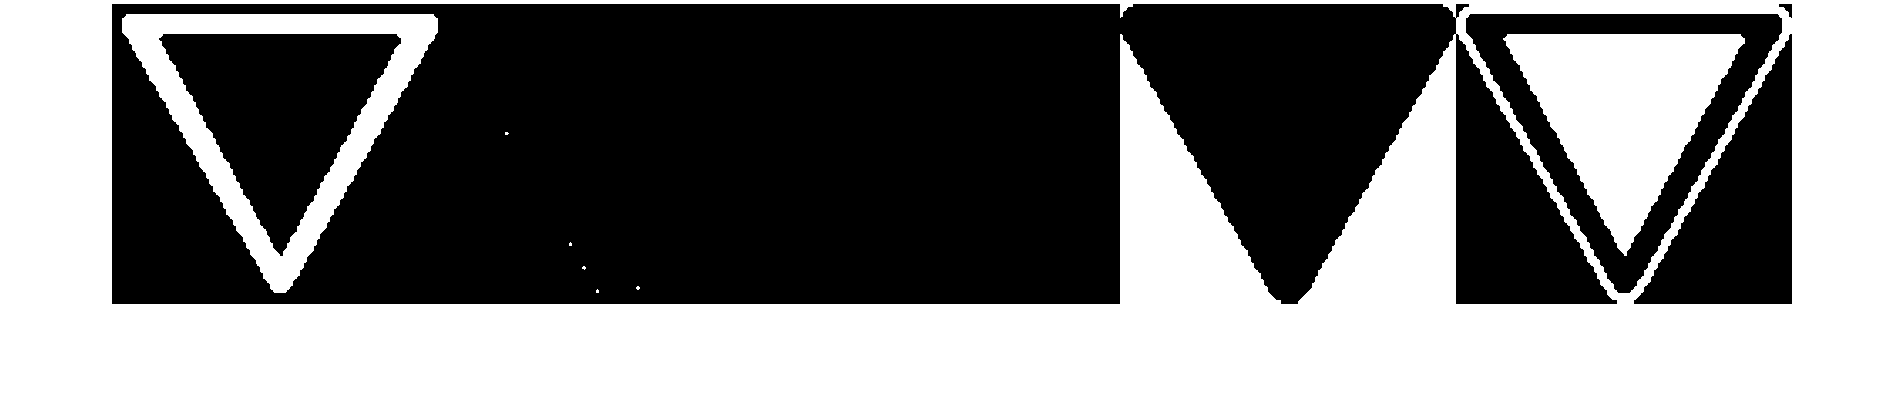

displaySign(13)

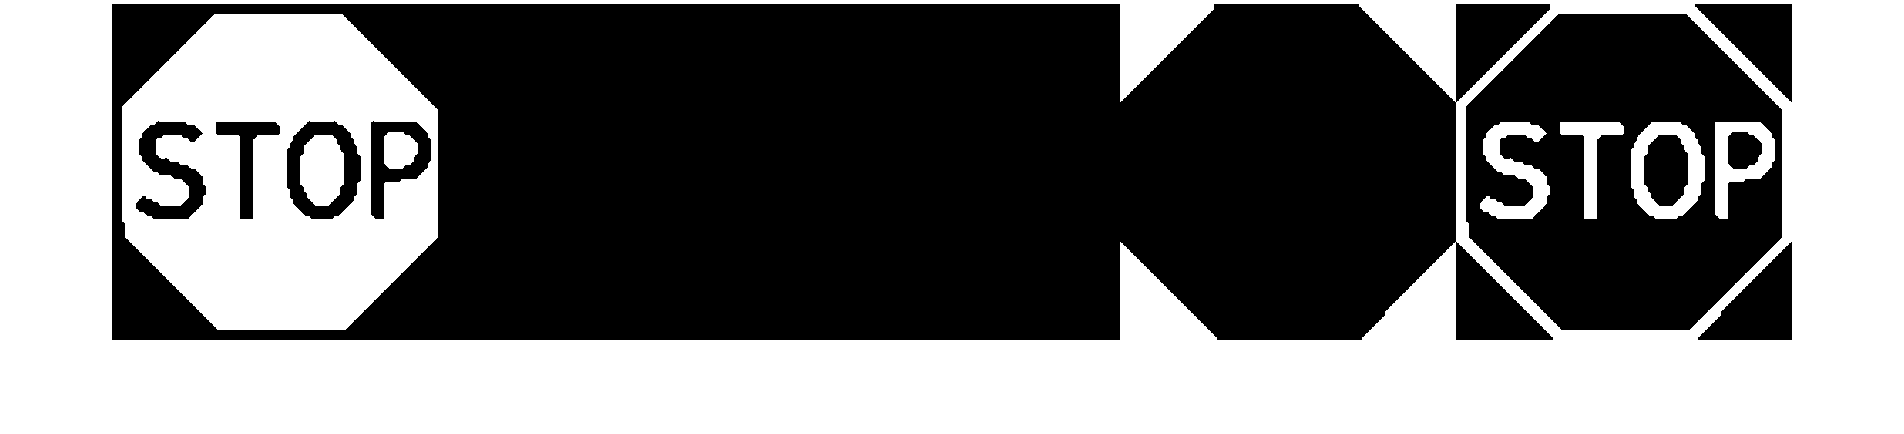

displaySign(14)

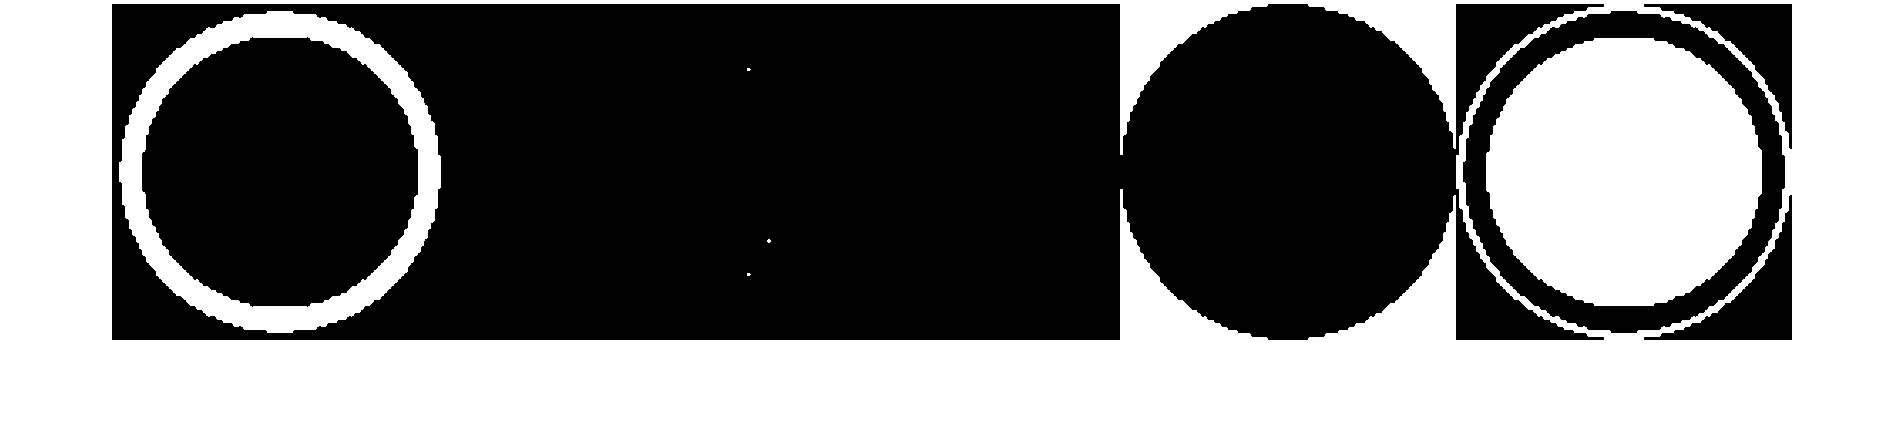

displaySign(15)

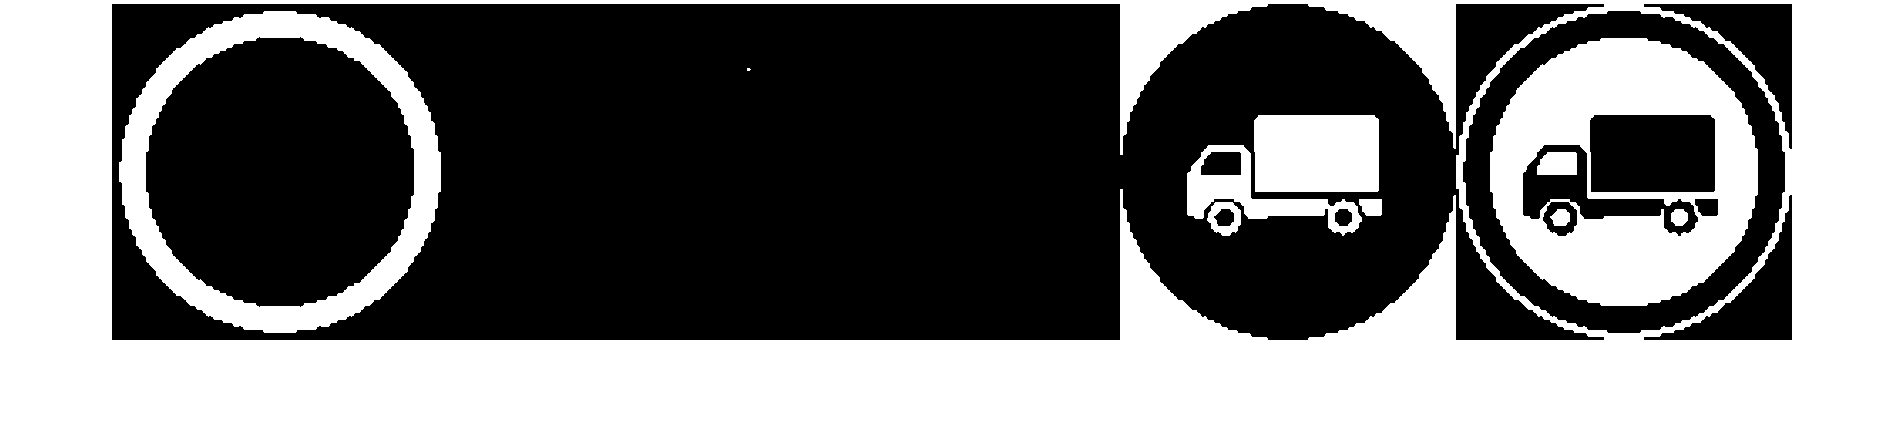

displaySign(16)

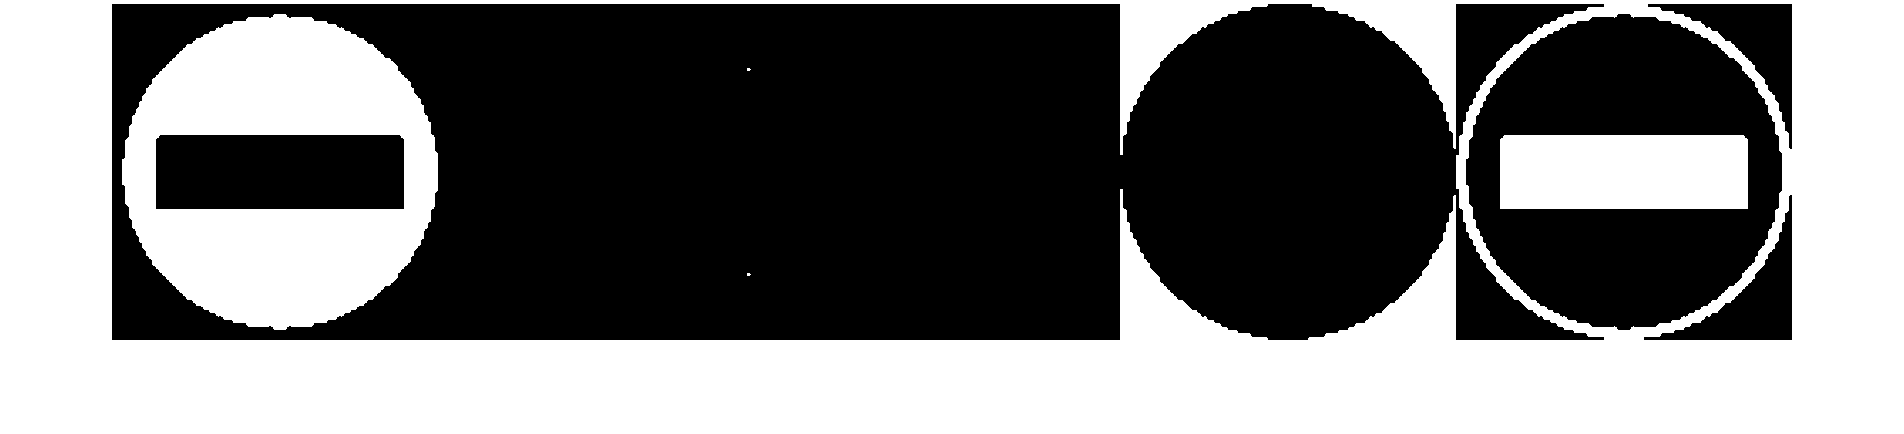

displaySign(17)

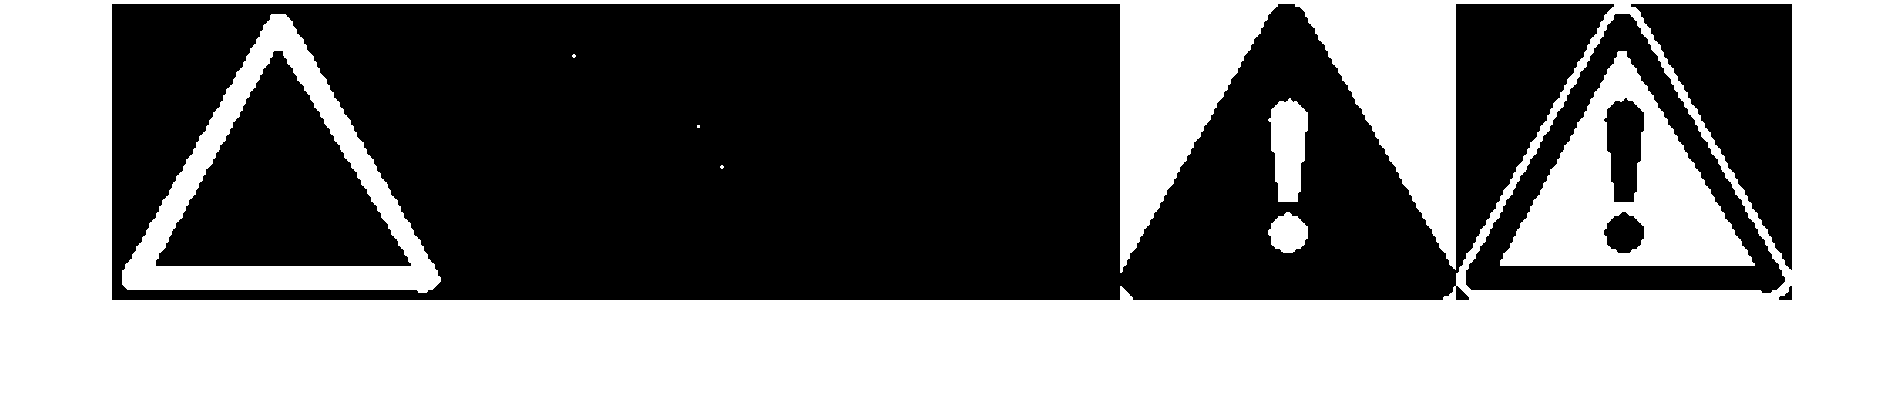

displaySign(18)

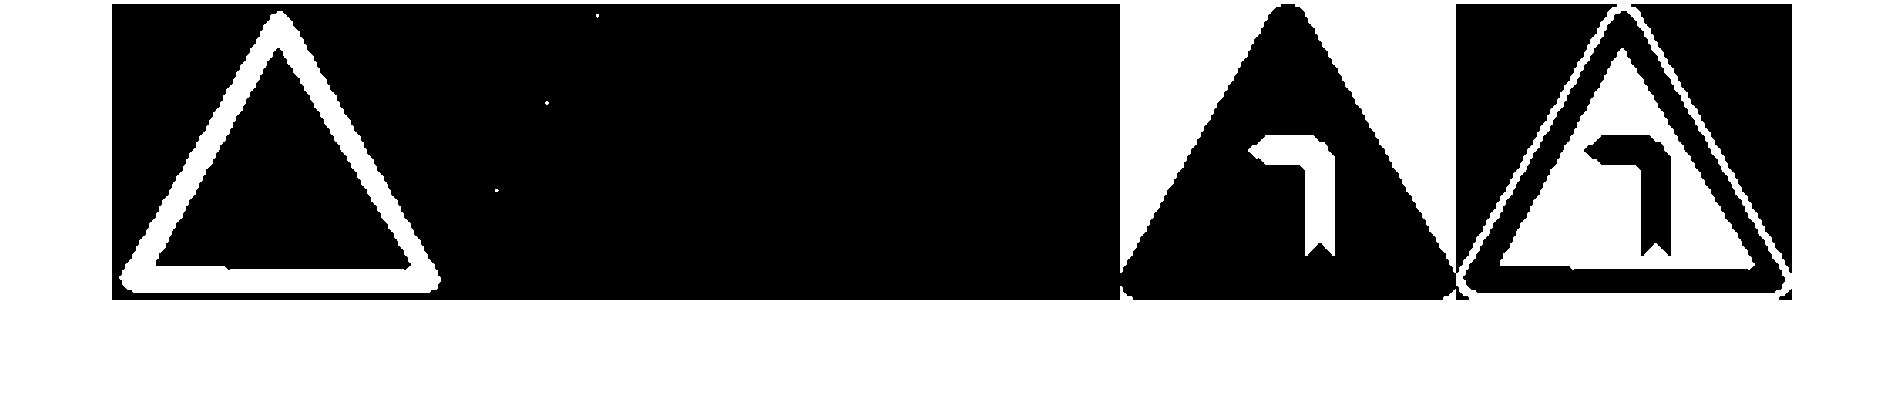

displaySign(19)

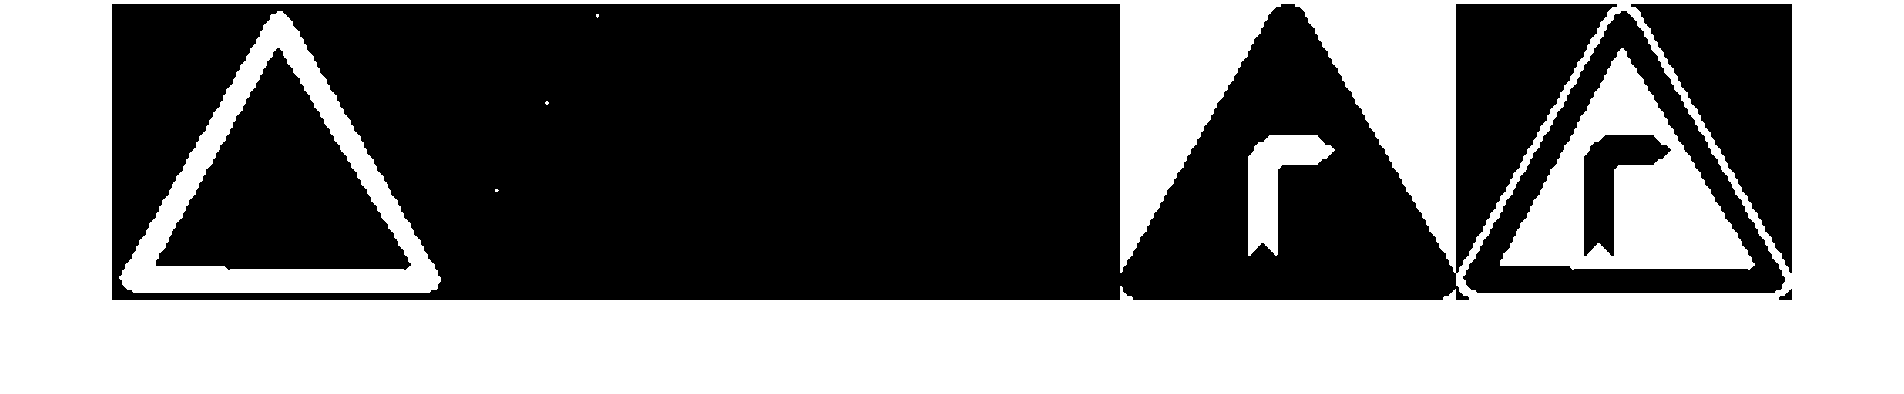

displaySign(20)

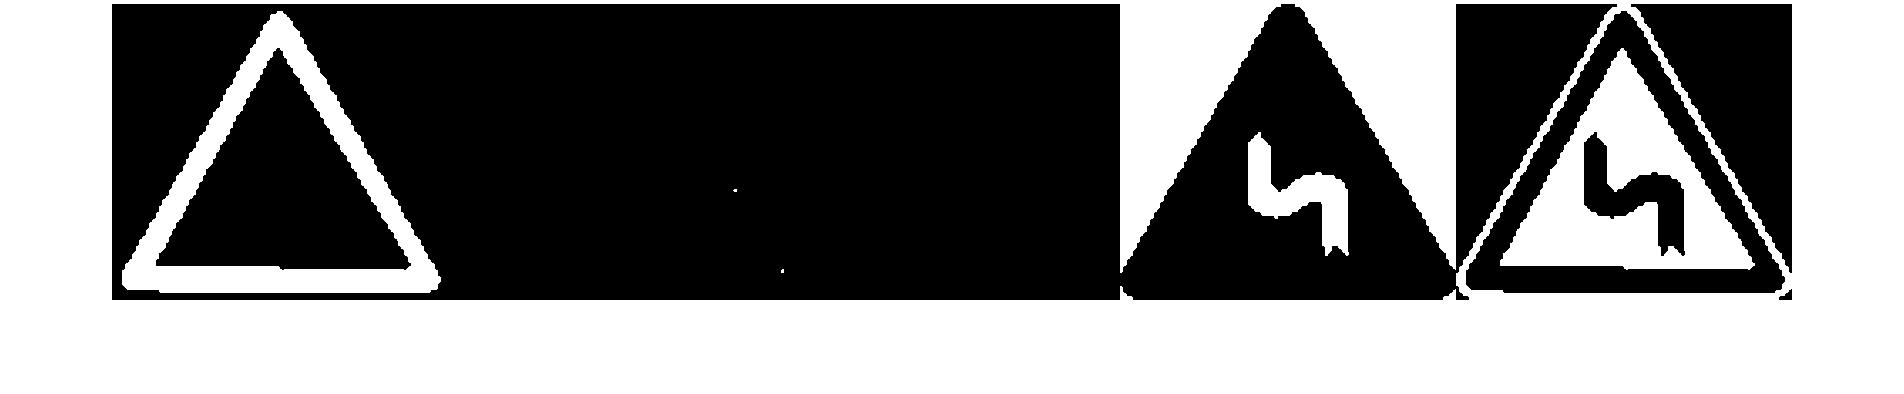

displaySign(21)

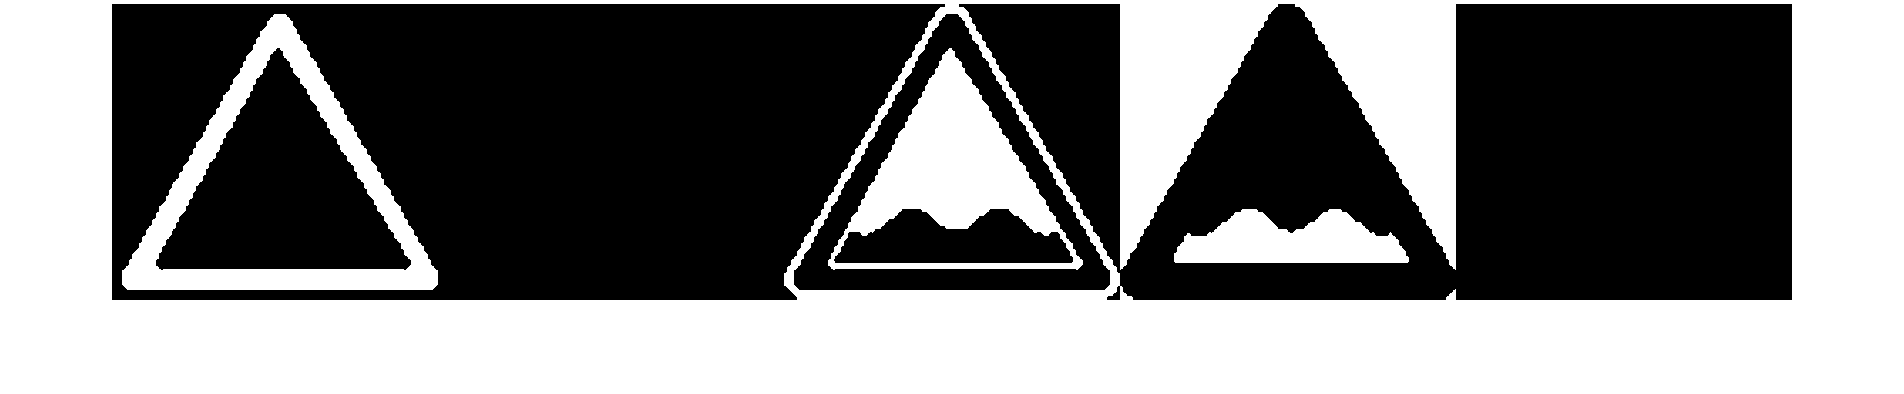

displaySign(22)

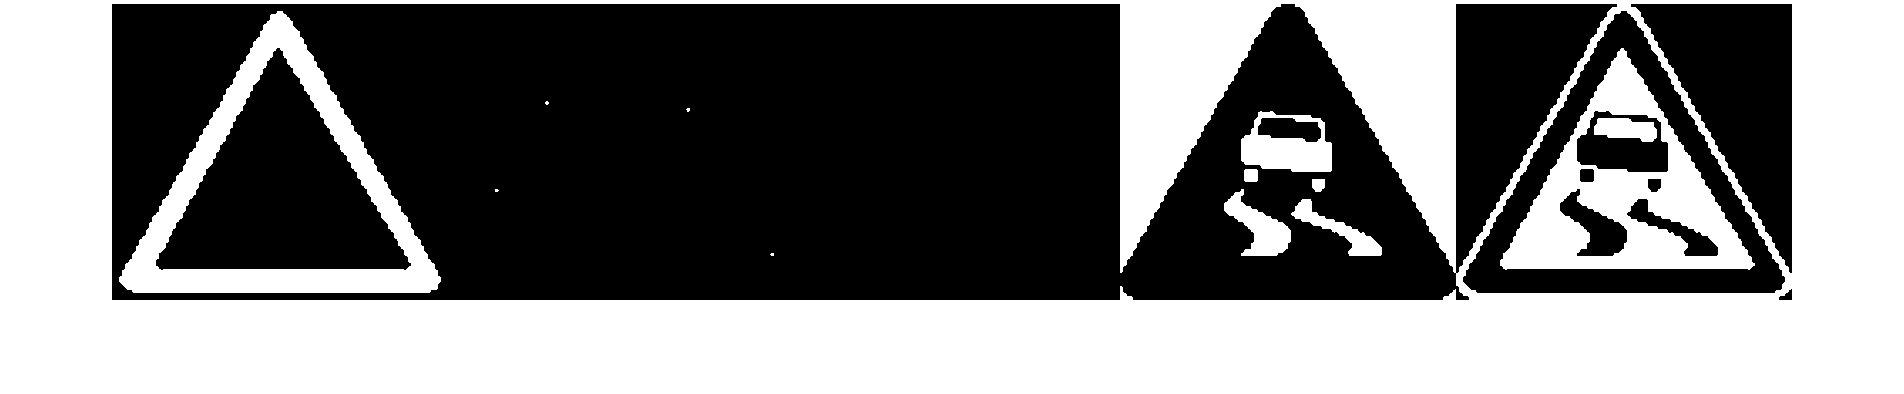

displaySign(23)

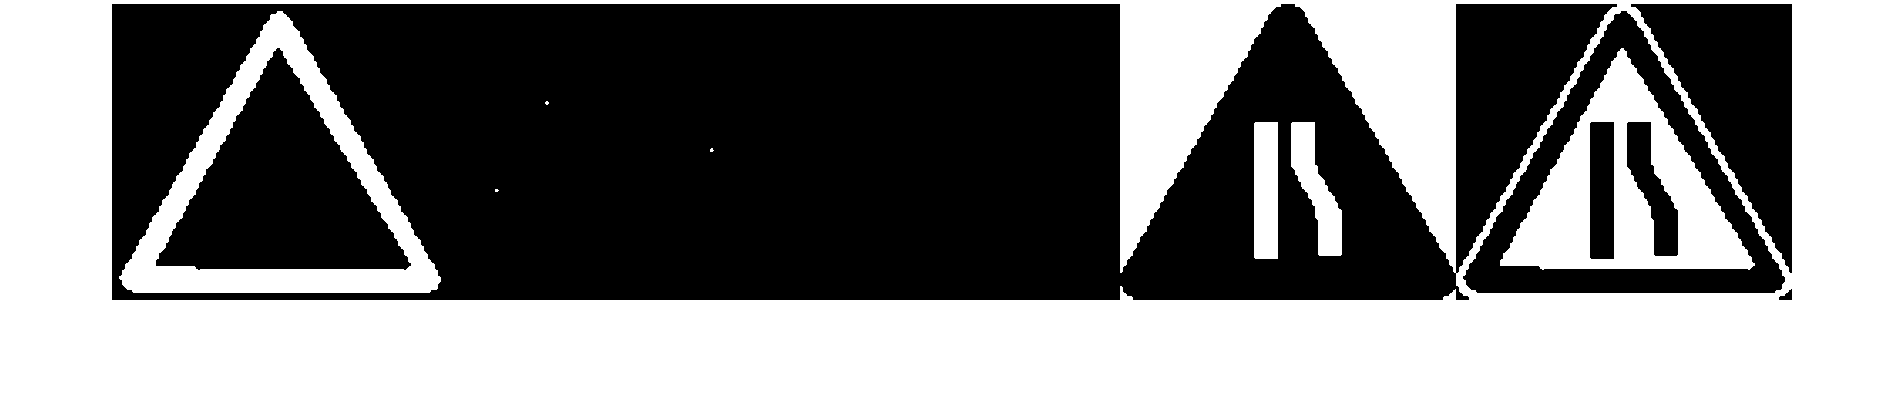

displaySign(24)

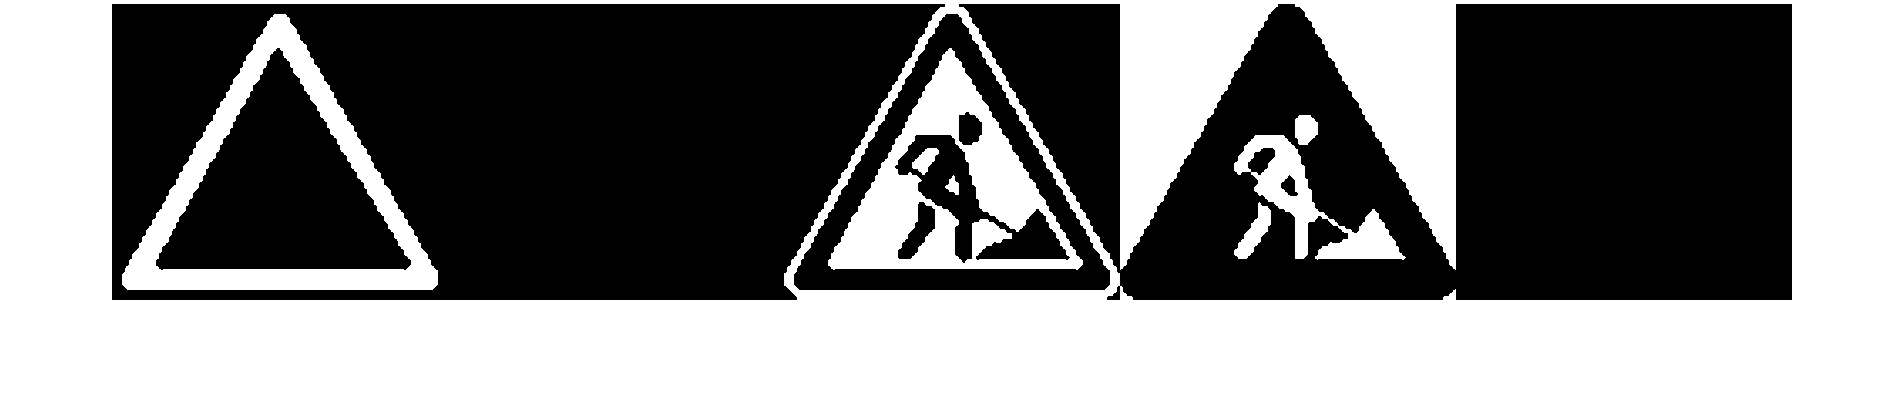

displaySign(25)

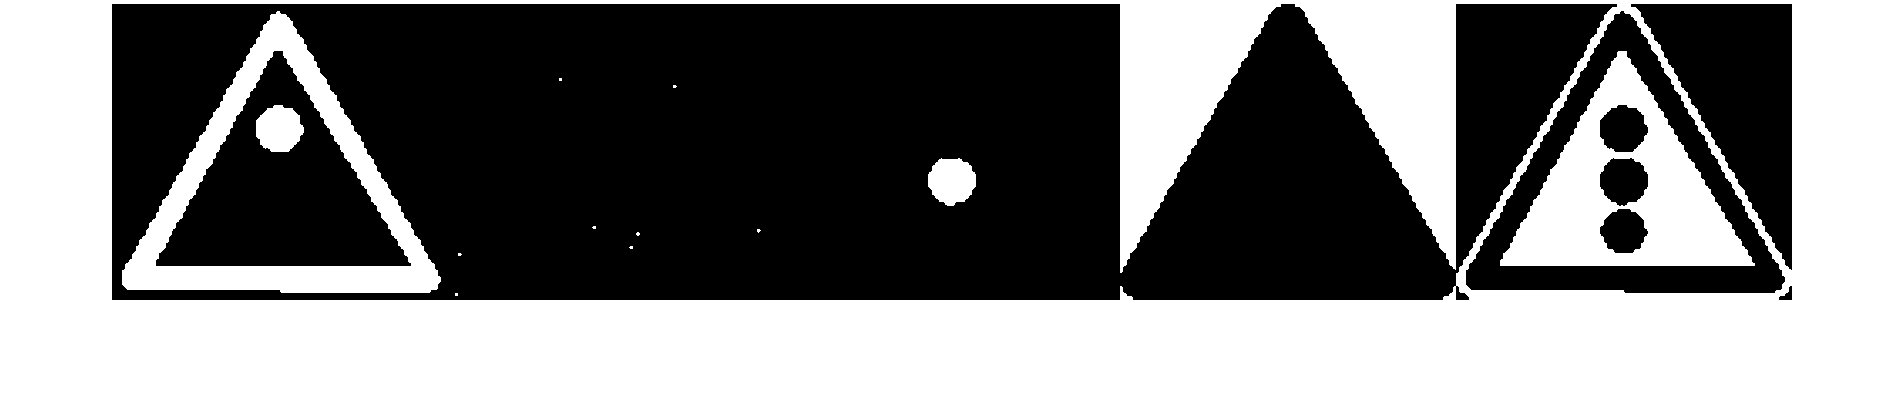

displaySign(26)

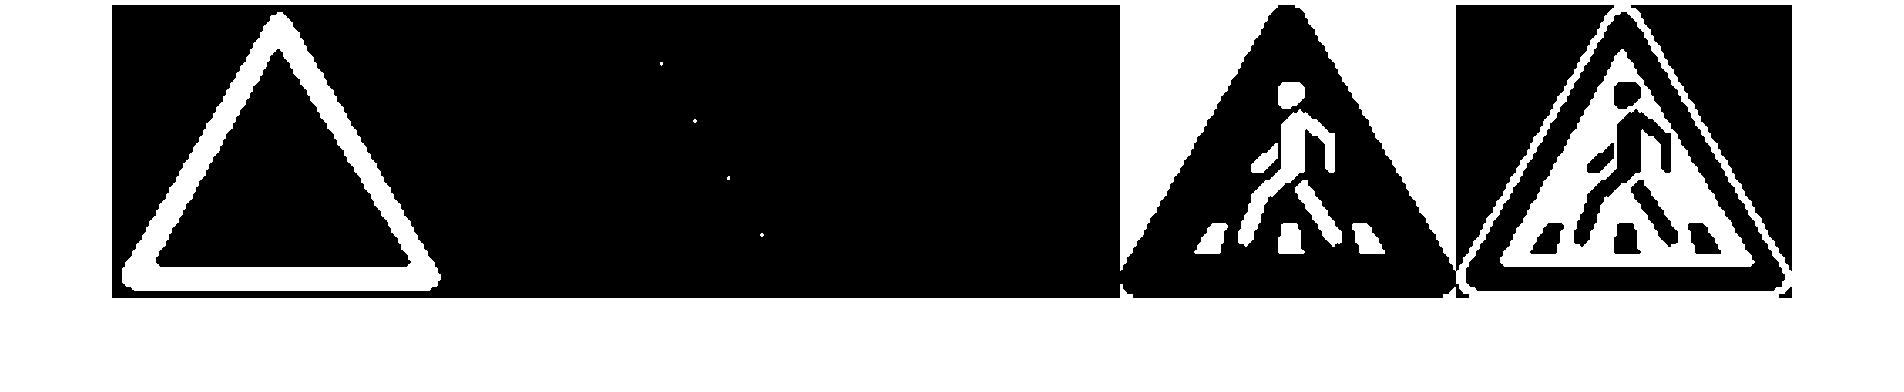

displaySign(27)

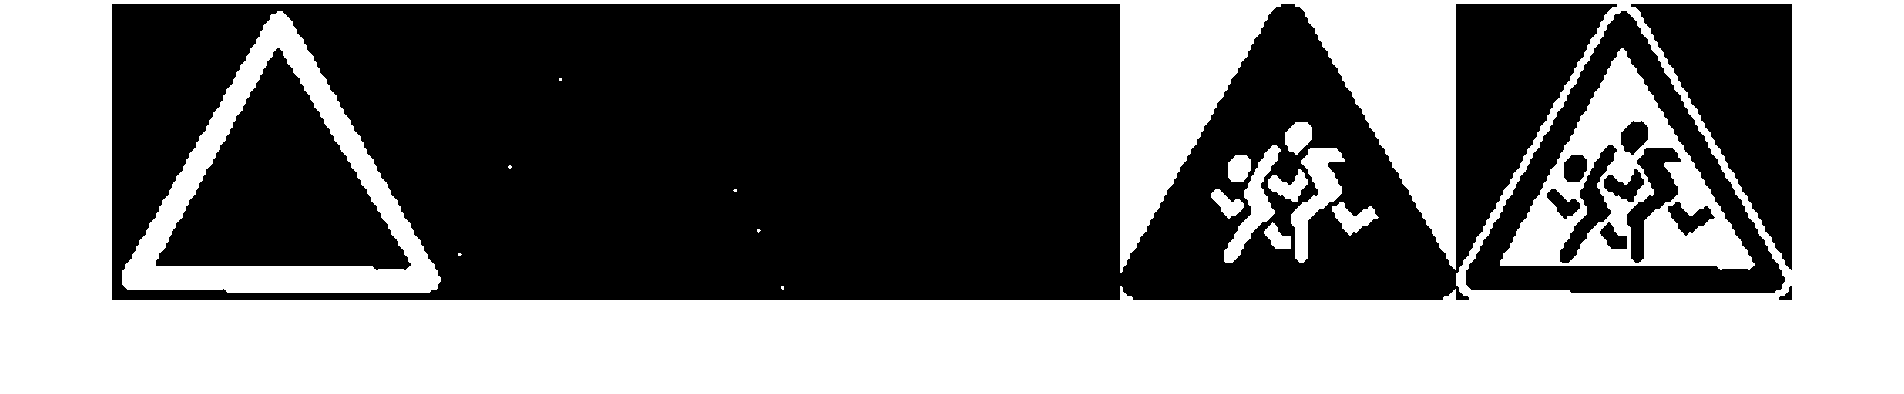

displaySign(28)

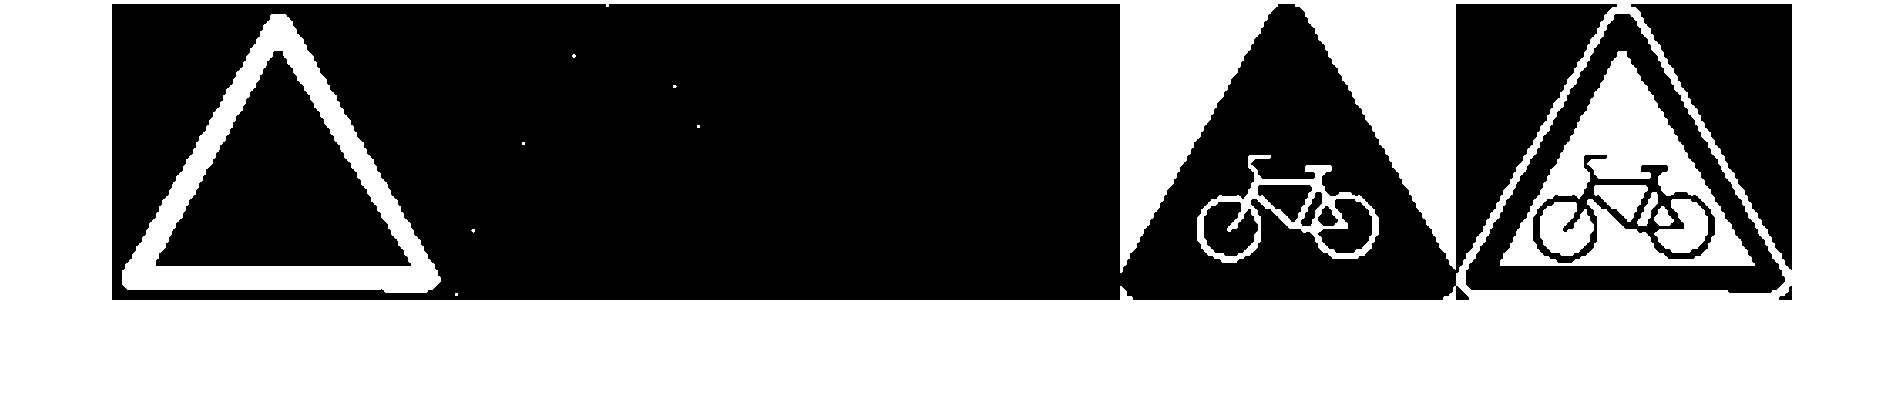

displaySign(29)

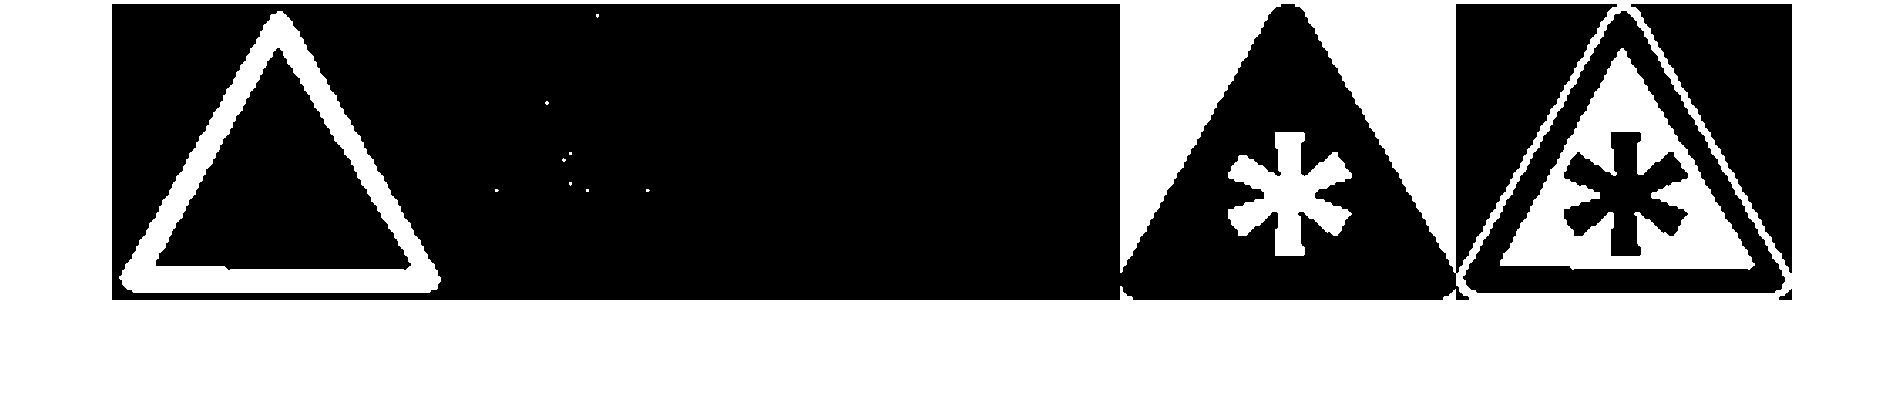

displaySign(30)

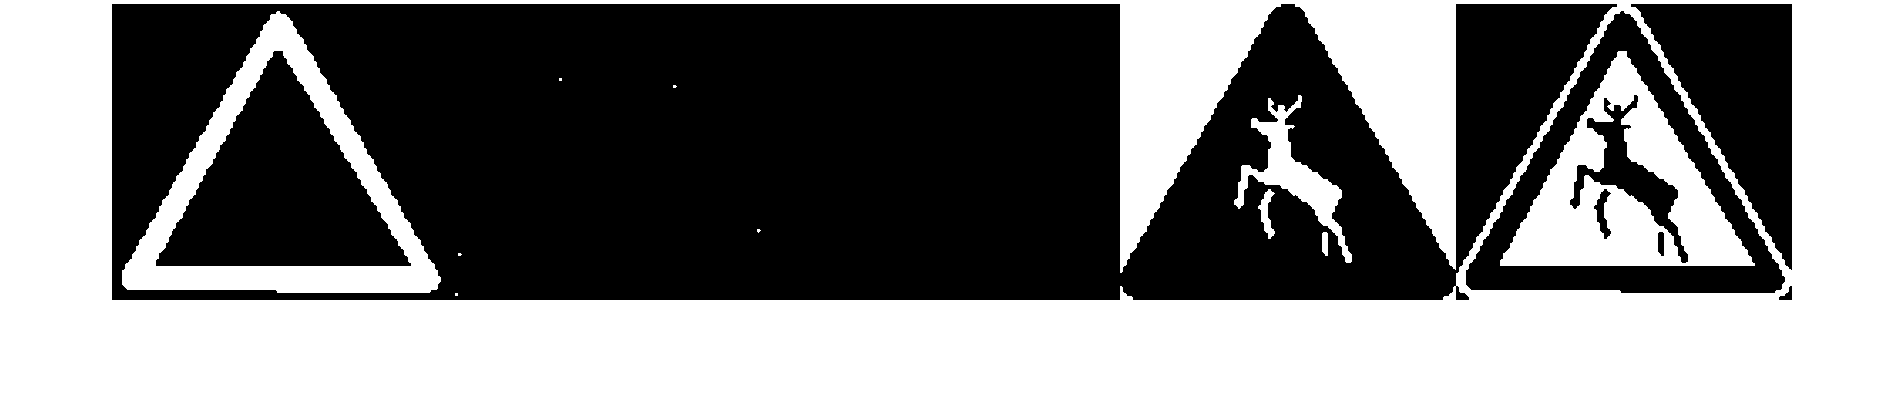

displaySign(31)

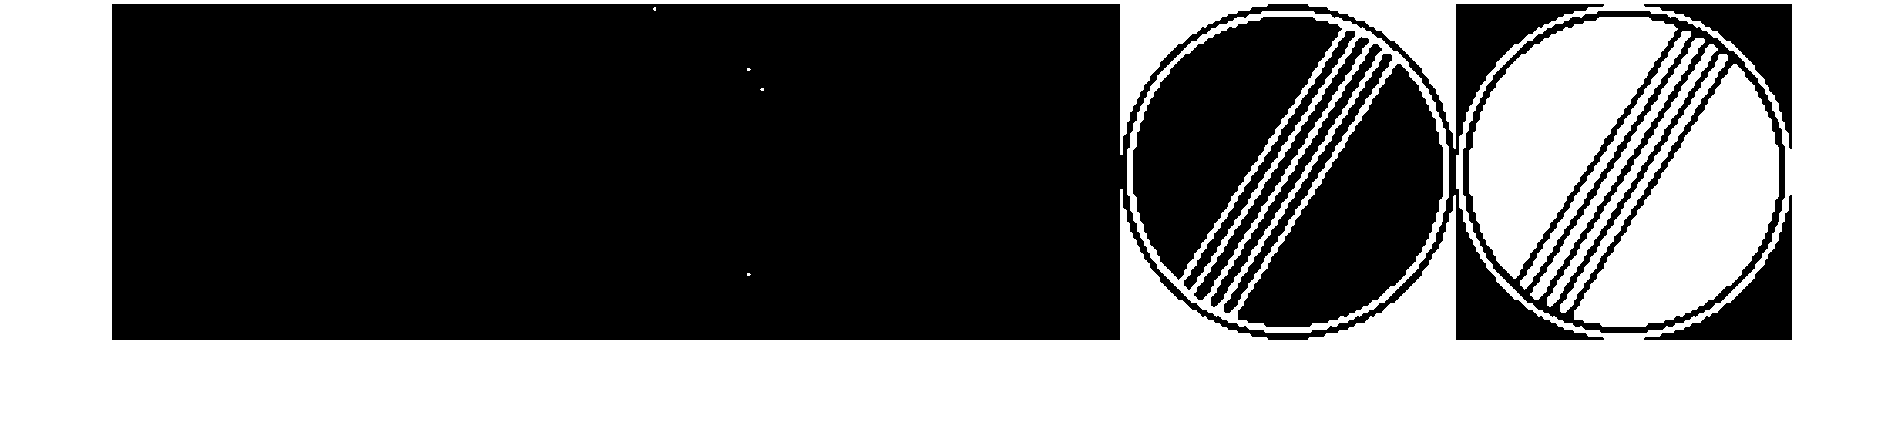

displaySign(32)

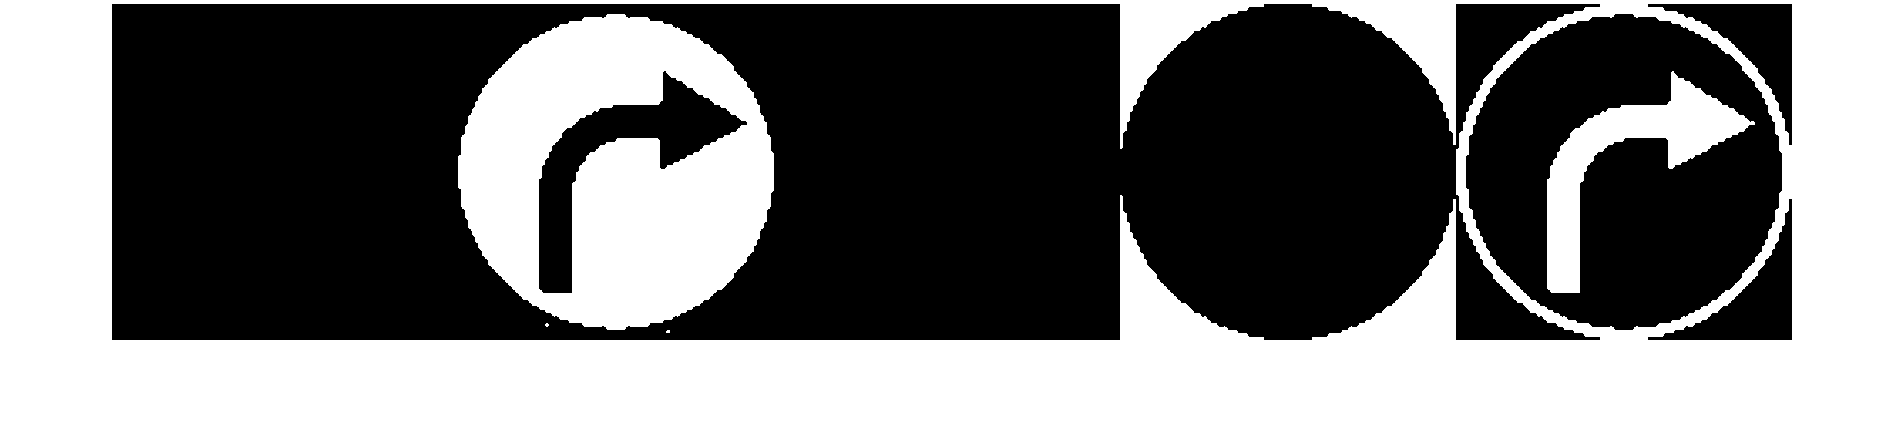

displaySign(33)

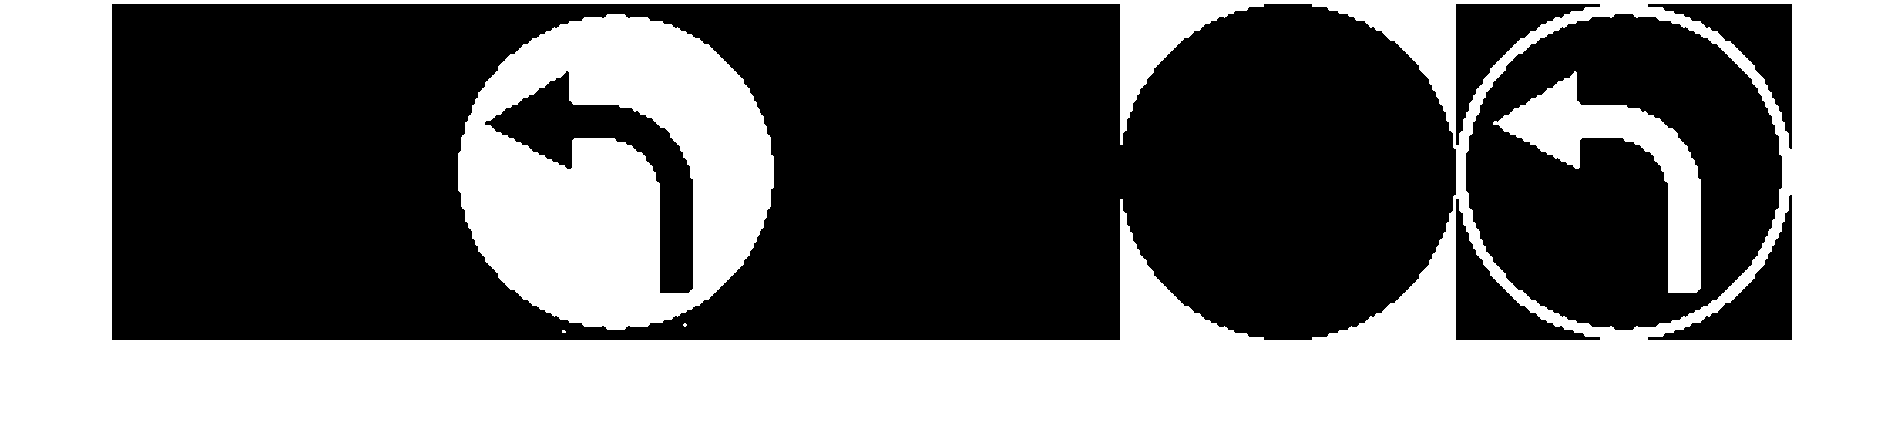

displaySign(34)

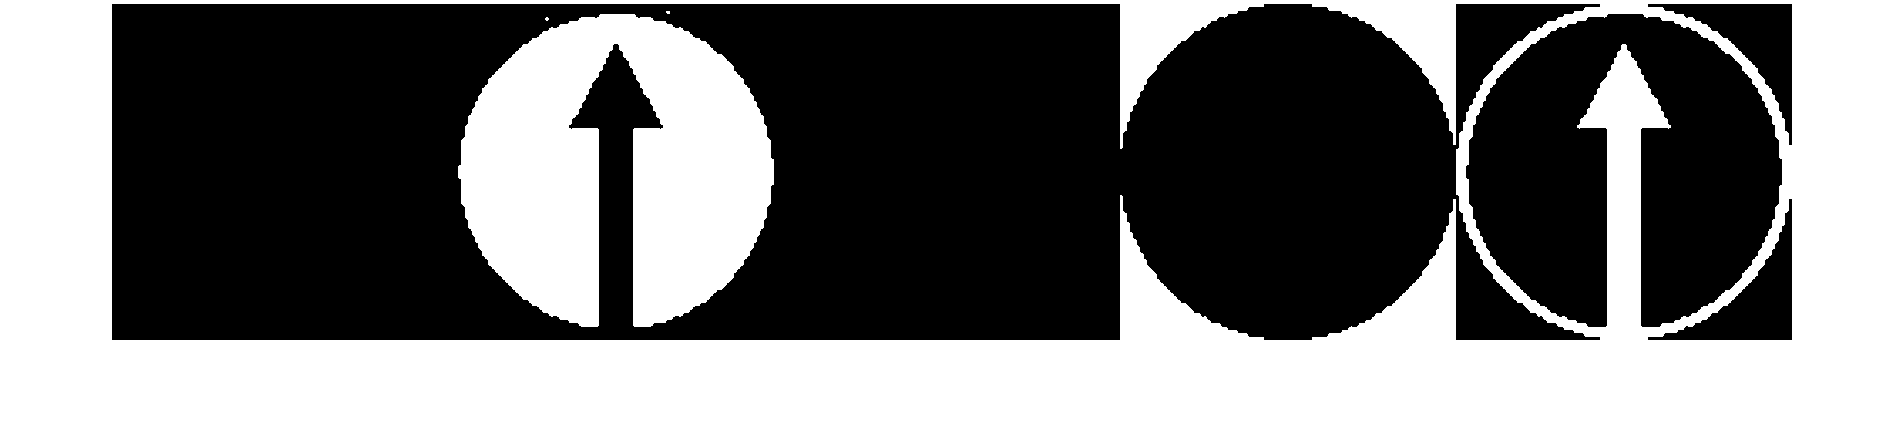

displaySign(35)

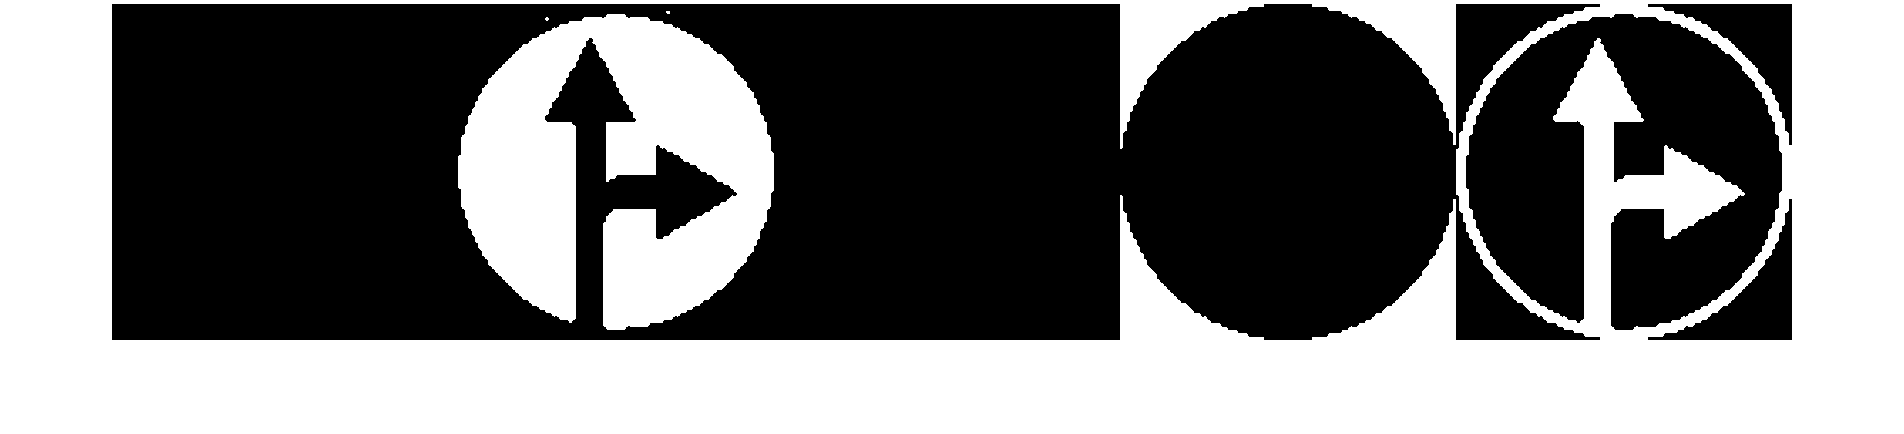

displaySign(36)

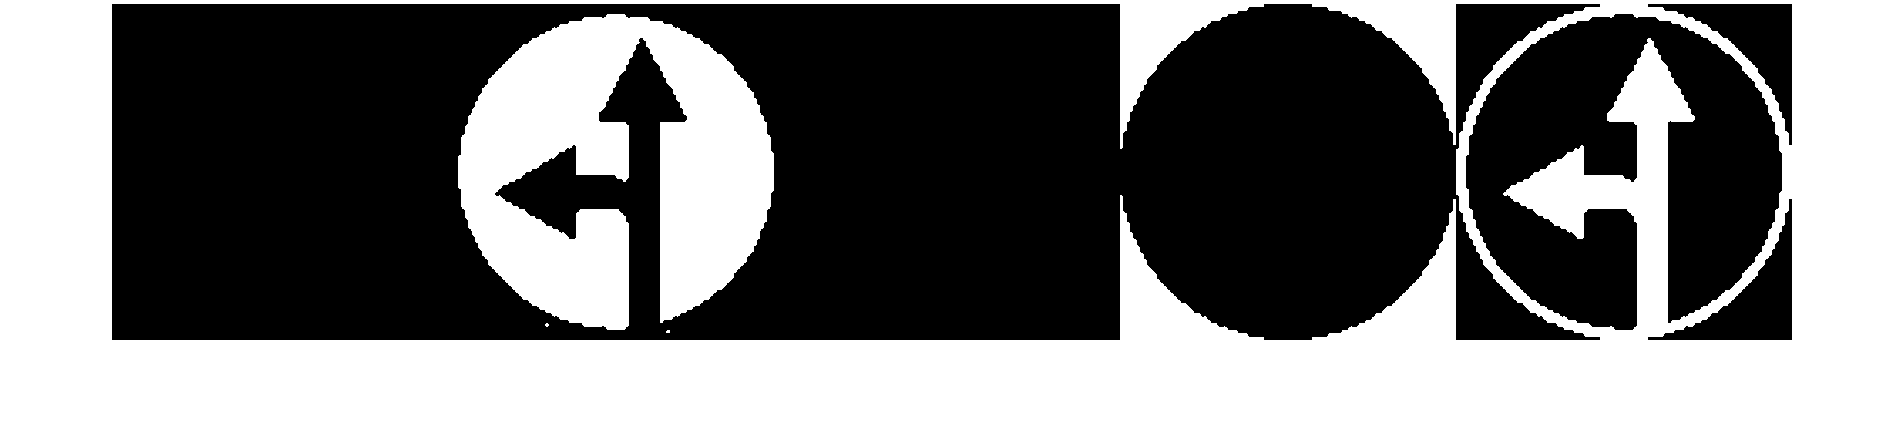

displaySign(37)

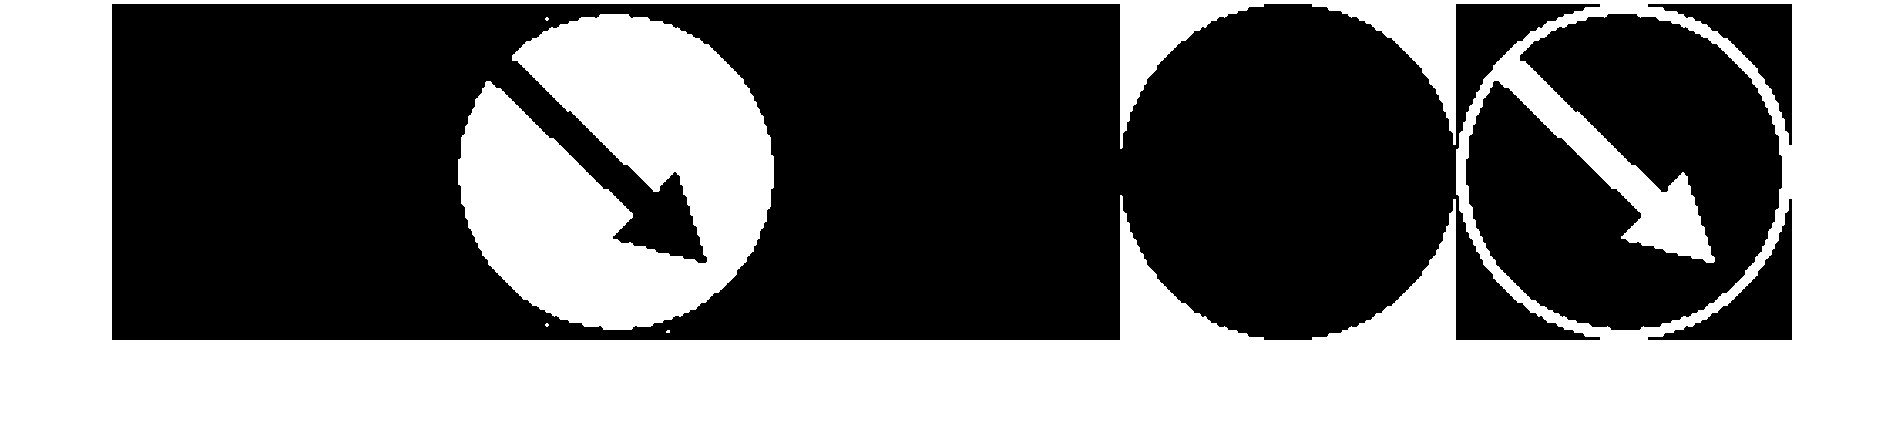

displaySign(38)

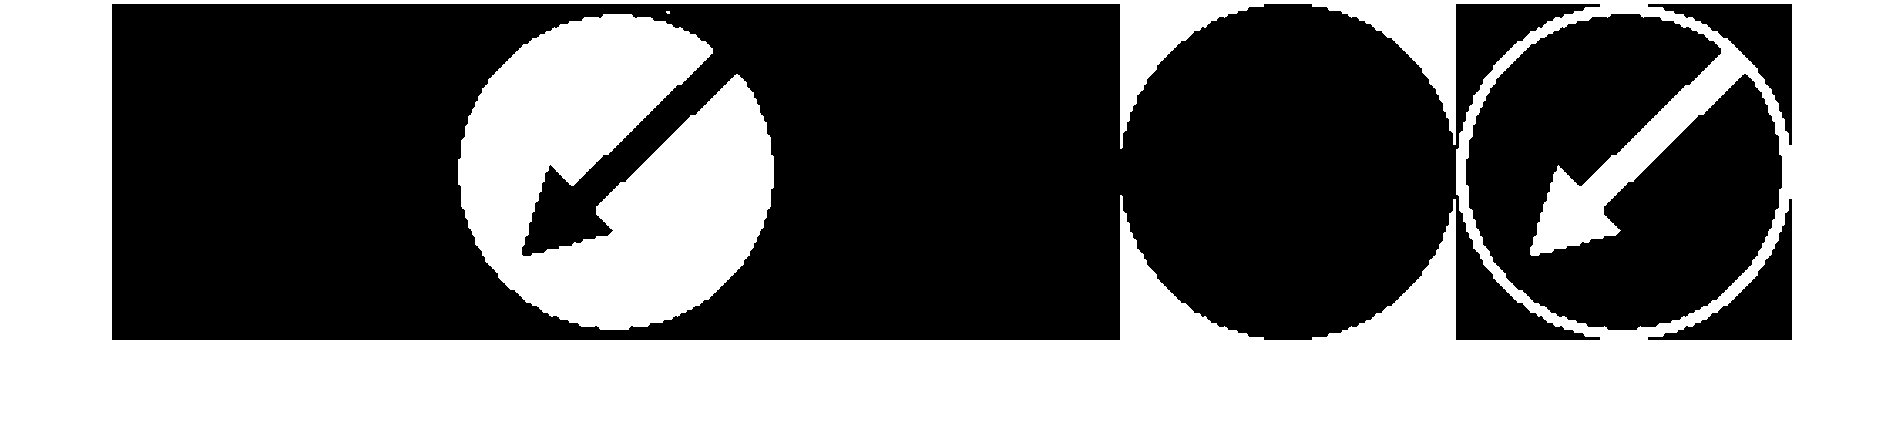

displaySign(39)

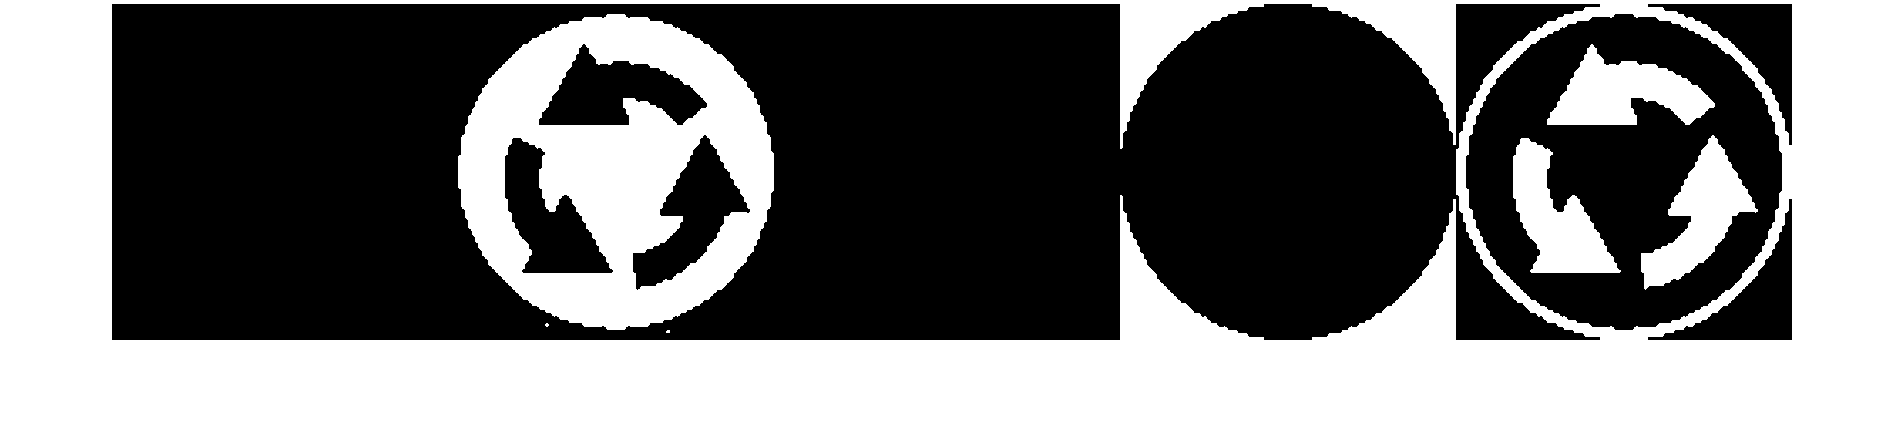

displaySign(40)

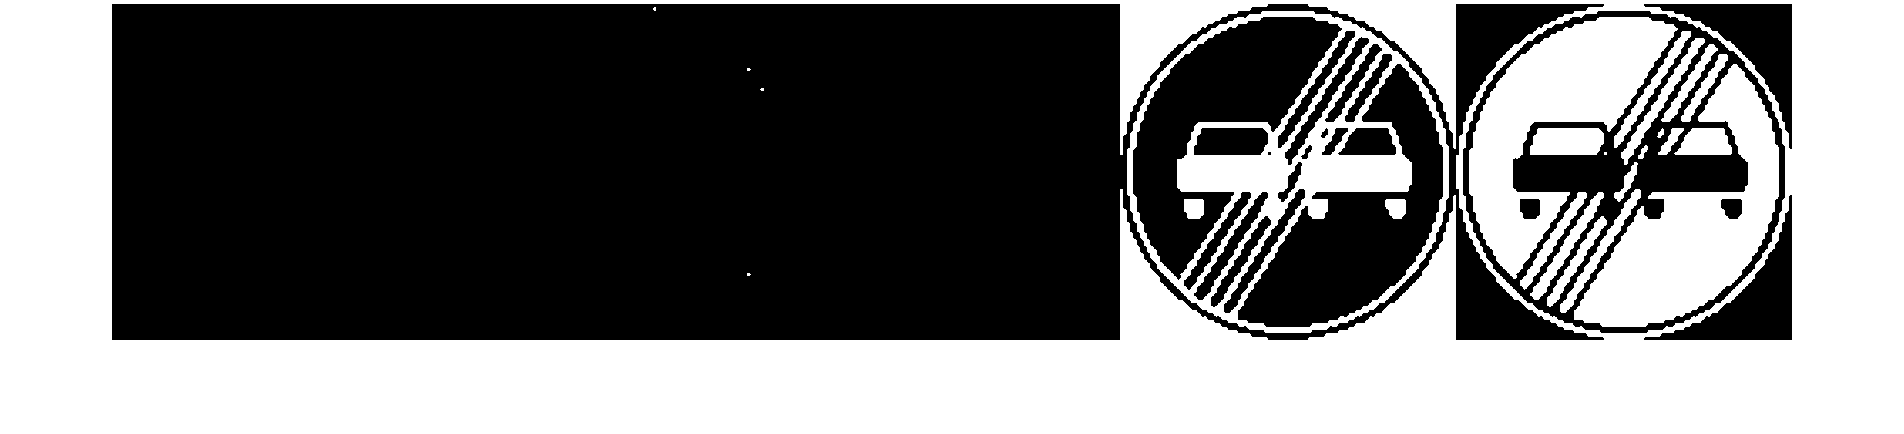

displaySign(41)

function displaySign(k)
    file = sprintf('../images/Meta/%d.png',k);
    img = imread(file);
    [red, blue, yellow, black, white] = splitColor(img);
    montage({red, blue, yellow, black, white}, "Size", [1,5]);
end

function [red, blue, yellow, black, white] = splitColor(img, maxDist)
    if (nargin < 2)
        maxDist = 0.5;
    end
    
    [H,S,V] = imsplit(rgb2hsv(img));
    
    r = num2cell([0.0139, 0.786, 0.786]);
    b = num2cell([0.5889, 0.78, 0.61]);
    y = num2cell([0.1583, 0.68, 1]);
    k = num2cell([0, 0, 0]);
    w = num2cell([0, 0, 1]);
    
    rD = distance(r{:}, H, S, V);
    bD = distance(b{:}, H, S, V);
    yD = distance(y{:}, H, S, V);
    kD = distance(k{:}, H, S, V);
    wD = distance(w{:}, H, S, V);
    
    red = rD < bD & rD < yD & rD < kD & rD < wD & rD < maxDist;
    blue = bD < rD & bD < yD & bD < kD & bD < wD & bD < maxDist;
    yellow = yD < rD & yD < bD & yD < kD & yD < wD & yD < maxDist;
    black = kD < rD & kD < bD & kD < yD & kD < wD & kD < maxDist;
    white = wD < rD & wD < bD & wD < yD & wD < kD & wD < maxDist;
end

function [dist] = distance(H, S, V, H2, S2, V2)
    cos1 = cos(2*pi * H) .* S .* V;
    sin1 = sin(2*pi * H) .* S .* V;
    v1 = V;
    
    cos2 = cos(2*pi * H2) .* S2 .* V2;
    sin2 = sin(2*pi * H2) .* S2 .* V2;
    v2 = V2;

    dist = sqrt((cos2 - cos1).^2 + (sin2 - sin1).^2 + (v2 - v1).^2);
end